# Análisis vertical    

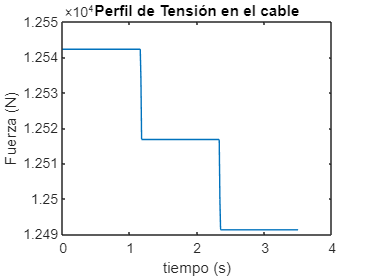

%Aceleración escogida vertical (Trapecoidal)
delta=0.01;
m=2;
t=0:delta:3.5;
vdef=m*ctramp(t)-m*ctramp(t-3.5/3)-m*ctramp(t-2*3.5/3);
adef=diff(vdef);
t=linspace(0,3.5,length(adef)); %Se redefine el tiempo para ajuste con la aceleración

%Estimaciones iniciales
masac=366.7;
densidadB=2.69/10/10/10;
masab=densidadB*130*130*20; %suposición de la bandeja

%Tensión en la cuerda 

N=masac*(adef+9.81);
T=masab*(adef+9.81)+N; %Sale de 2

plot(t,T)
title('Perfil de Tensión en el cable')
xlabel('tiempo (s)')
ylabel('Fuerza (N)')


% %{Torque en la base 
% Mb=N*1.22+masab*9.81*3/4*1.22; 
% plot(t,Mb)
% title('Perfil de torque en la base')
% xlabel('tiempo (s)')
% ylabel('Torque (N m)')